# Linear Control Design II - Group Work Problem Module 4

## Description

**Problem 1** Solve Problem 2.10 from the textbook.

**Solution****:**

Four heat equations are given:


$$q_{c}=k_{c}T_{s}-T_{a}\\q_{g}=k_{g}T_{s}-T_{g}\\q_{r}=k_{r}\left(T_{s}^{4}-T_{a}^{4}\right)\\q=ku$$


**1.1 Nonlinear model and state space model**

$C_s\,\,and\,\,C_g$ are the heat capacities. The expression for the time derivatives of the temperatures for the differernt parts of the system can be written as:

the change of heat = heat_in - heat_out

For the oven, the heat balance equation can be written as:


$$C_s\dot{T}_s=q-q_r-q_c-q_g$$



$$\dot{T}_s=\frac{1}{C_s}\left((-k_c-k_g)T_s-k_rT_s^4+k_gT_g+ku+k_cT_a+k_rT_a^4\right)$$


For the product, the heat balance can be written as:


$$C_g\dot{T}_g=q_g$$



$$\dot{T}_g=\frac{1}{C_g}(k_gT_s-k_gT_g)$$


$T_s\,\,and\,\,T_g$ are chosen as the state variables: $x=\left[\matrix{x_1 \cr x_2}\right]=\left[\matrix{T_s \cr T_g}\right]$. $T_a$ is considered as the disturbance and is called $v$. The state space model can now be written as:


$$\mathbf{\dot{x}}=\left[\matrix{\frac{1}{C_s}((-k_c-k_g)x_1-k_rx_1^4+k_gx_2) 
\cr
\frac{1}{C_g}k_g(x_1-x_2)
}\right]
+
\left[\matrix{\frac{1}{C_s}k 
\cr
0
}\right]u
+
\left[\matrix{\frac{1}{C_s}k_cv+k_rv^4
\cr
0
}\right]
$$



$$y=\left[\matrix{0&1}\right]\mathbf{x}$$


**1.2 Stationary state**

Stationarty state means, no more changes will happen in the system. That is to say all the time derivatives of $T_s$ and $T_g$ will be zero at this state. And the equations are solved for the state vector $\mathbf{x}$ and the control input $u$


$$0=q-q_c-q_r-q_g\\0=q_gu$$


This leds to:

\\ In the solution, it says $T_{s0}=T_{g0}$, why?


$$T_{s0}\\
T_{g0}\\
\\ 
0=q-q_r-q_c-q_g\\
0=q_g\rightarrow\\
q=q_c-q_r\rightarrow\\
u_0=\frac{1}{k}(k_c(T_{s0}-T_a)+k_r(T_{s0}^4-T_a^4))$$


**1.3 Linerarization**

At the stationary point, we can do the linerarization. We define:


$$T_s=x_1=x_{10}+\Delta x_1\\
T_g=x_2=x_{20}+\Delta x_2\\
u=u_0+\Delta u\\
T_a=v=v_0+\Delta v$$


The components of the vector field $\mathbf{f}(\mathbf{x},u,v)$is given by:


$$	f_1 = \dot{x_1} = \frac{1}{C_s}(ku-(k_c+k_g)x_1+k_gx_2+k_cv-k_rx_1^4+k_rv^4) \\
	f_2 = \dot{x_2} = \frac{1}{C_g}k_g(x_1-x_2)$$


The system matrix can now be derived from formula (2.66), (2.68), (2.69) and (2.67) from the textbook.


$$A=\frac{\partial \mathbf{f}(\mathbf{x_0},u_0,v_0)}{\partial \mathbf{x}}=\left[\matrix{\frac{1}{C_s}(-k_c-k_g-4k_rx_{10}^3 &\frac{k_g}{C_s}
\cr
\frac{k_g}{C_g} &-\frac{k_g}{C_g}
}\right]$$



$$B=\frac{\partial \mathbf{f}(\mathbf{x_0},u_0,v_0)}{\partial u}=\left[\matrix{\frac{k}{C_s} \cr  0}\right]$$



$$B_v=\frac{\partial \mathbf{f} (\mathbf{x_0},u_0,v_0)}{\partial v}=\left[\matrix{\frac{1}{C_s}(k_c+4k_rv_0^3)
\cr
0}
 \right]$$



$$C=\left[\matrix{0&1}\right]$$
 

**Problem 2** Implement a model of the system in the Simulink environment, and use the following numerical values for the model parameters


$$k_c = 0.85 \,W/^{\circ}C \\ k_g = 1.2 \,W/^{\circ}C \\ k_r = 7.8\cdot 10^{-10} \,W/K^4 \\ C_s = 75 \,J/^{\circ}C \\ C_g = 800 \,J/^{\circ}C \\ k = 100 \,W/V$$


The control signal $u$ can assume values in the interval $0-10\,V$.

**Note that you must use absolute temperatures.**

Carry out simulations on the model with the initial values $u_0 = 5\,V$, $T_{si} = 200^{\circ}C$, $T_{gi} = 25^{\circ}C$ and $T_a = 25^{\circ}C$. Determine the stationary state by simulation until all variables have assumed constant values.

**Solution****:**

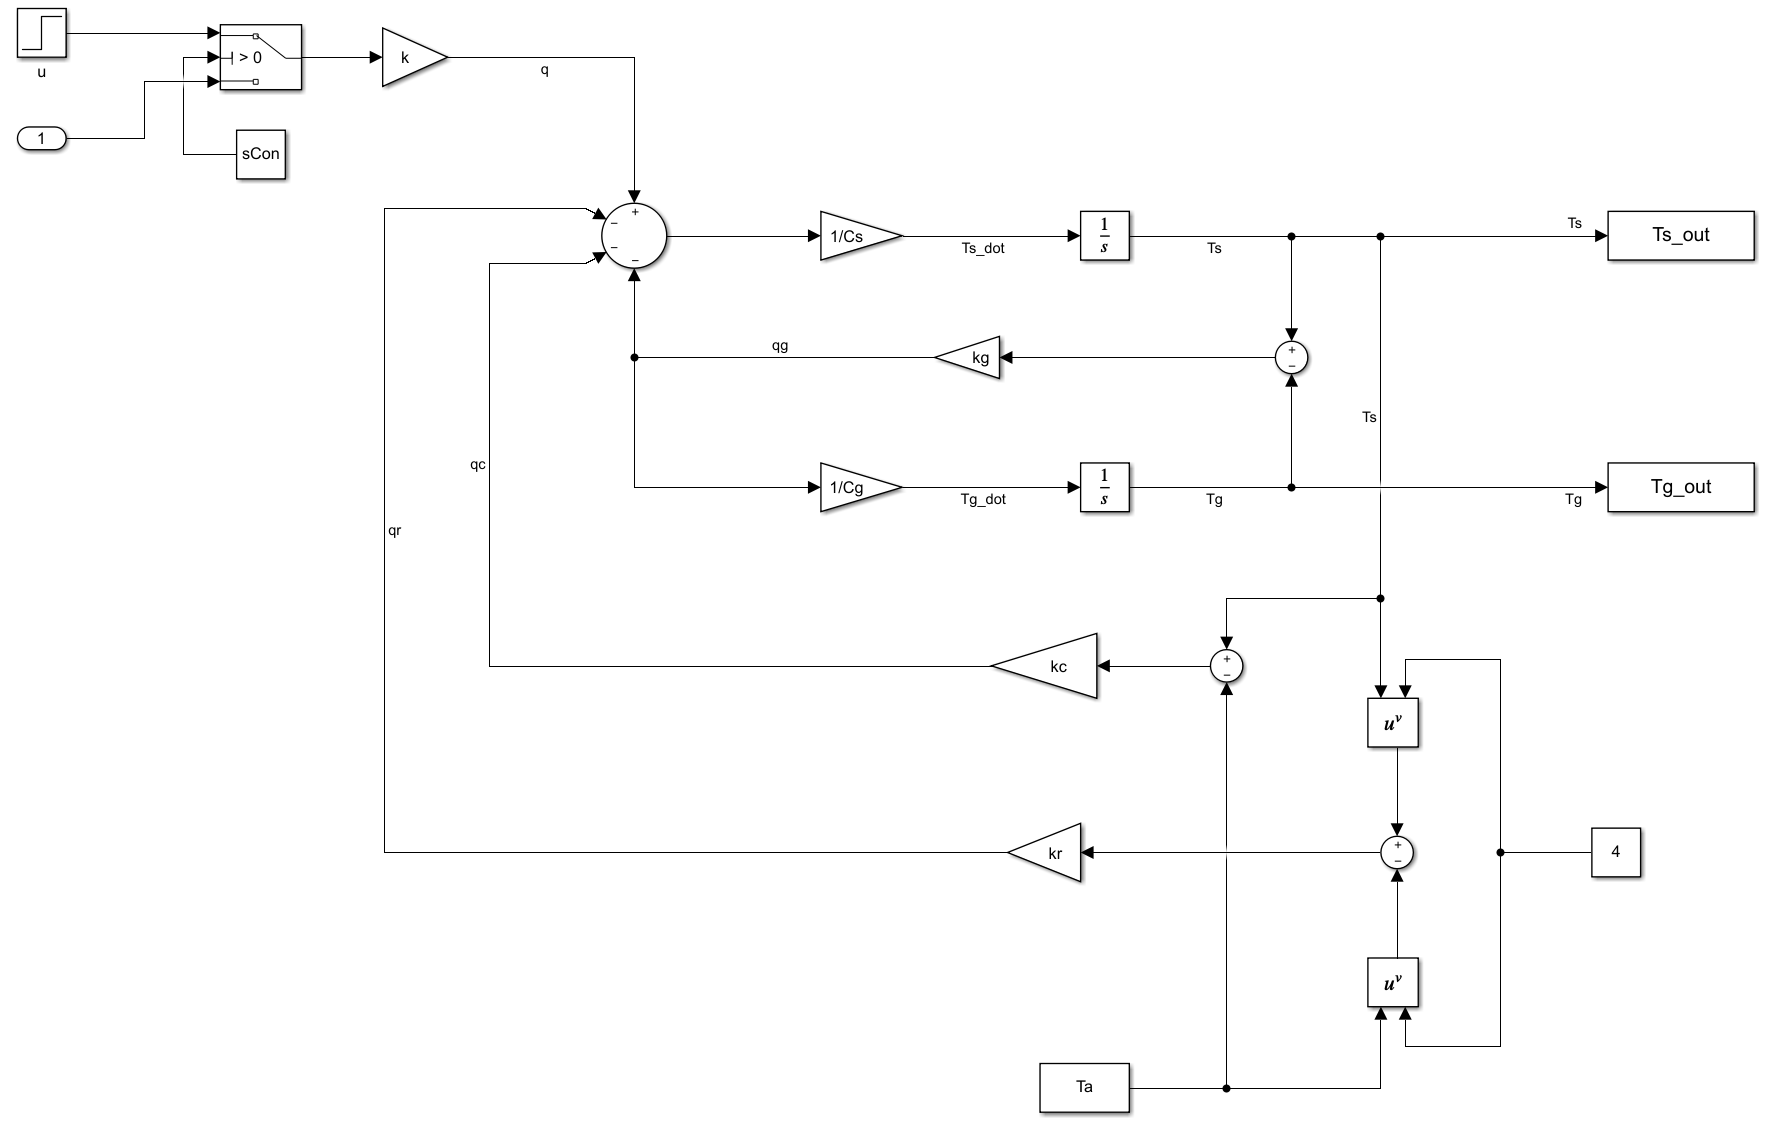

Figure 1: Simulink block diagram of the oven model

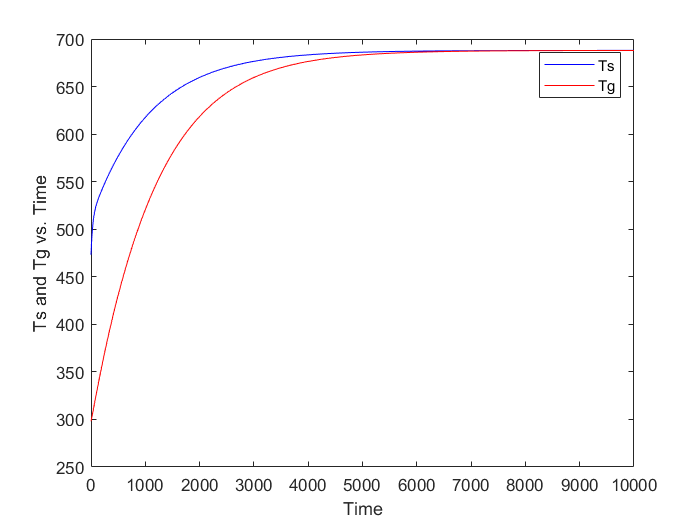

% Your solution goes here:
kc = 0.85; % Watt/deg.C
kg = 1.2; % Watt/deg.C
kr = 7.8e-10; % Watt/K^4
Cs = 75; % Joule/deg.C
Cg = 800; %Joule/deg.C
k = 100; %Watt/volt
Ta = 298.15; %K 274.15+25
u0 = 5; % v

    %u0 is set to the constant value of 5 volts
    %Ta is set to the constant value of 298.15K
    %Tsi is set to 473.15K in the integrator initial condition
    %Tgi is set to 298.15K in the integrator initial condition
sCon = 1; % 1 for stepinput/ 0 for IN
sim("ovenModel");

figure
plot(Ts_out.time, Ts_out.signals.values, 'b', Ts_out.time, Tg_out.signals.values,'r');
xlabel('Time');
ylabel('Ts and Tg vs. Time');
legend('Ts', 'Tg');

As can be seen from the plot, the values finally stabilize around 688 K which is 414.85 degrees Celsius. The setting time is around 5500 times units.

If use these stationary values along with the initial data in equation(15) then will get an input of u:

u_0 = 1/k * (kc*(688-Ta)+kr*(688^4-Ta^4))

u_0 =        4.9997


u will get 4.997 which is pretty close to our initial input 5v

**Problem 3**  Linearize the nonlinear Simulink model applying the Matlab function `linmod`. Use the function as follows

`[A,B,C,D] = linmod('modelname',x0,u0)`

where $x_0$ and $u_0$ are the stationary states and inputs.

Compare the result with that from the manual linearization from question "c'' in the Problem 2.10.

Find the eigenvalues of the $\mathbf{A}$ matrix by using the Matlab function `eig()`. Repeat the linearization for $u_0 = 2\,V$ and $u_0 = 8\,V$; $T_a = 10^{\circ}C$ and  $T_a = 35^{\circ}C$, and note

how the linear model changes with the stationary state.

Remove the radiation effect (set $k_r = 0$) and repeat the linearization for different values $u_0$.

**Solution****:**

**1) Linearize the nonlinear Simulink model applying linmod()**

% Your solution goes here:
sCon = 0;
x=Simulink.BlockDiagram.getInitialState('ovenModel');
[A,B,C,D]=linmod('ovenModel',x,[u0])

A =       -0.0015       0.0015
        0.016     -0.03174


B =             0
       1.3333


C =      1     0


D =      0


eigenval = eig(A)

eigenval =   -0.00072615
    -0.032514


The eigenvalues of the dynamic matrix are found $\lambda_1=-0.0325\,,\lambda_2=-0.0007$. Note that both eigenvalues are in the left-half of complex plane.

**2) set **$u_0=2$v and 8v

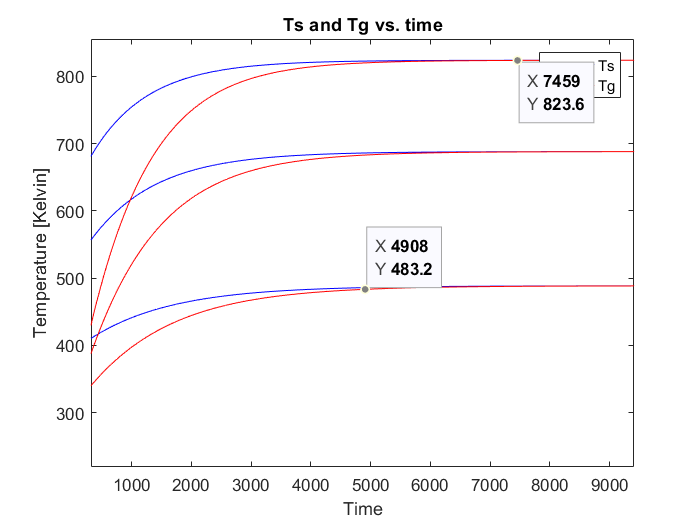

%The constants...
kc = 0.85; %Watt/deg.C
kg = 1.2;  %Watt/deg.C
kr = 7.8e-10; %Watt/K^4
Cs = 75;   %Joule/deg.C
Cg = 800;  %Joule/deg.C
k  = 100;  %Watt/volt
Ta = 298.15; %K
u = [2 5 8]; %V
figure
sCon = 1; %setting sCon to 1 take the stepinput, setting sCon to 0 take the IN.
for i=1:3
    u0=u(i);
 sim('ovenModel')
 plot(Ts_out.time,Ts_out.signals.values,'b' ,Ts_out.time, Tg_out.signals.values,'r')
 hold on
 xlabel('Time');
 ylabel('Temperature [Kelvin]');
 title('Ts and Tg vs. time');
 legend('Ts', 'Tg');
end

**3) Set **$T_a=10^{\circ}C \,and\,T_a=35^{\circ}C$

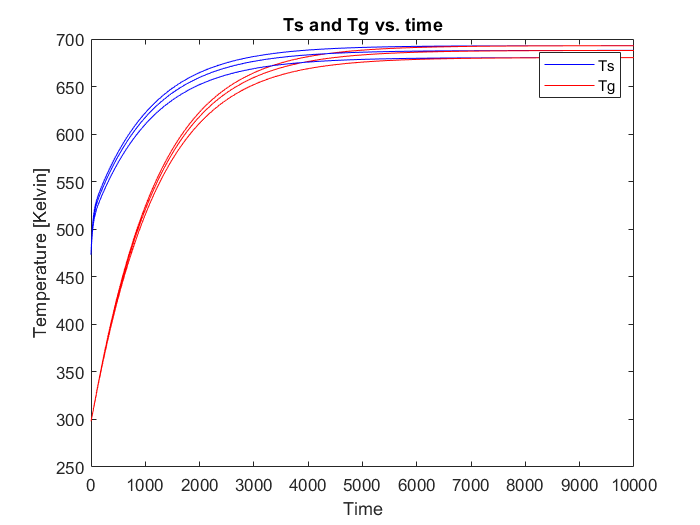

Ta1=[308.15 298.15 283.15];
u0=5;
figure
for i=1:3
    Ta=Ta1(i);
    sCon=1;
    sim('ovenModel')
    plot(Ts_out.time,Ts_out.signals.values,'b' ,Ts_out.time, Tg_out.signals.values,'r')
     hold on
     xlabel('Time');
     ylabel('Temperature [Kelvin]');
     title('Ts and Tg vs. time');
     legend('Ts', 'Tg');
end

The result shows that the higher outside temperature, the higher inner temperature.

**4) Remove the radiation effect (set **$k_r = 0$**) and repeat the linearization for different values **$u_0$**.**

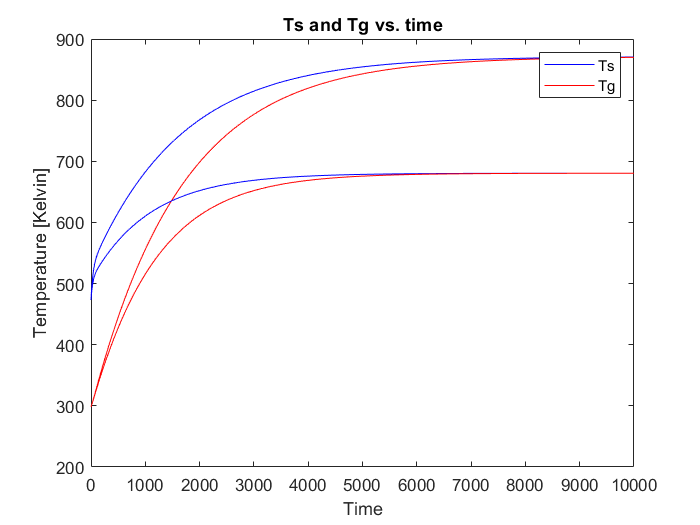

kr1=[0 7.8e-10];
u0=5;
figure
for i=1:2 
    kr=kr1(i);
    sCon = 1; %setting sCon to 1 take the stepinput, setting sCon to 0 take the IN.
    sim('ovenModel')
    plot(Ts_out.time,Ts_out.signals.values,'b', Ts_out.time, Tg_out.signals.values,'r')
    hold on
    xlabel('Time');
    ylabel('Temperature [Kelvin]');
    title('Ts and Tg vs. time');
    legend('Ts', 'Tg');
end